%ACW - Michael Hughes

%Load Image
[file,path] = uigetfile('*.jpg');
if isequal(file,0)
   disp('User selected Cancel');
   return
else
   disp(['User selected ', fullfile(path,file)]);
end

User selected D:\mikey\Documents\GitHub\Computer-Vision-ACW\Images\starfish_noise5.jpg


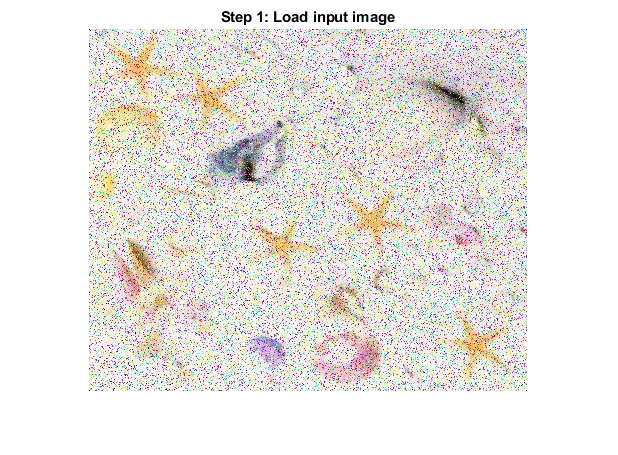




Img = imread(fullfile(path,file));
imshow(Img), title('Step 1: Load input image');

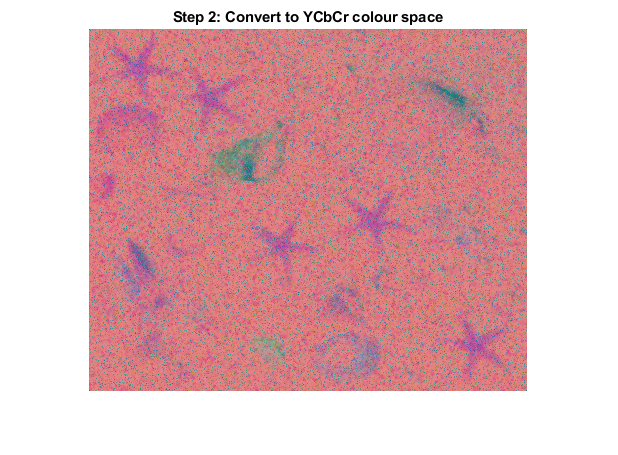

%Convert to different Colour Space
spImage = rgb2ycbcr(Img);
imshow(spImage), title('Step 2: Convert to YCbCr colour space');

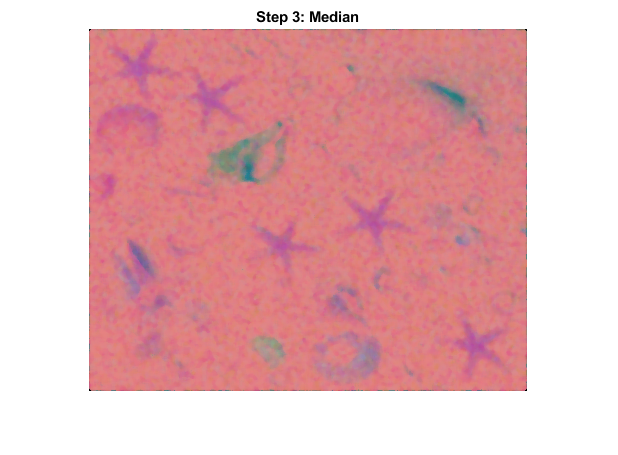

%Filters

%median
img_median = spImage;
for c = 1 : 3
    img_median(:, :, c) = medfilt2(spImage(:, :, c), [5, 5]);
end
imshow(img_median)
title('Step 3: Median')

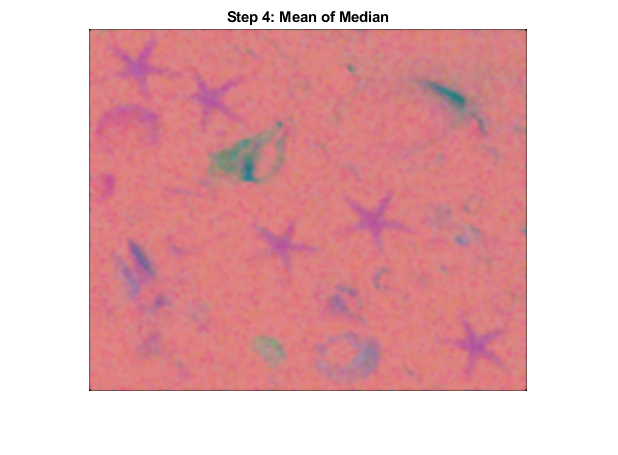


% 3x3 mean kernel
kernel = ones(3,3)/9; %1/9* ones(2) 

img_mean = img_median;
for c=1:3
     img_mean(:, :, c) = conv2(img_median(:, :, c),kernel,"same");
%J = conv2(I, kernel, 'same');
end
% Convolve keeping size of I
imshow(img_mean)
title('Step 4: Mean of Median')

% % % 3x3 mean kernel
% % kernel =1/3* ones(2);
% % img_mean = Img2;
% % for c=1:3
% %      img_mean(:, :, c) = conv2(Img2(:, :, c),kernel,"same");
% % %J = conv2(I, kernel, 'same');
% % end
% %Convolve keeping size of I
% img_mean = Img2
% for c = 1:3
%     img_mean(:,:,c) = filter2(fspecial('average',3),Img2(:,:,c))/255;
% end
% % 
% % h = 1/3*ones(3,1);
% % H = h*h';
% % % im be your image
% % img_mean = filter2(H,img_median);
% 
% 
% 
% img_median = img_mean;
% for c = 1 : 3
%     img_median(:, :, c) = medfilt2(img_mean(:, :, c), [3, 3]);
% end
% imshow(img_median), title('Step 3: Median Filter')

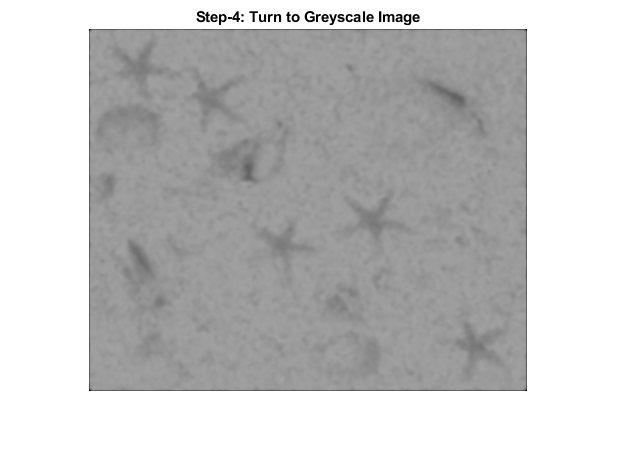

img_enhance = rgb2gray((img_mean));
imshow(img_enhance);
title('Step-4: Turn to Greyscale Image');

I4=img_enhance

I4 = 362×438 uint8 matrix
    17    50    84   100   100   100   101   100   100    99    98    97    96    95    94    94    96    96    94    93    91    91    90    91    92    94    94    95    97   100   102   102   101   101   100   100   100   102   103   103   103   103   103   101   101    99    97    95    94    94
    50   101   135   152   152   153   154   153   152   151   150   149   147   146   145   145   146   146   145   144   142   140   140   142   144   145   145   147   150   152   154   155   153   153   152   152   153   154   156   156   156   155   154   153   153   151   148   146   146   147
    84   136   154   156   157   158   158   157   156   155   154   153   153   152   152   151   151   151   151   149   148   147   148   150   151   153   153   154   155   157   157   157   157   156   156   155   155   156   157   158   158   157   156   155   154   154   153   153   153   154
   101   154   156   158   158   159   159   158   157   155   155   15

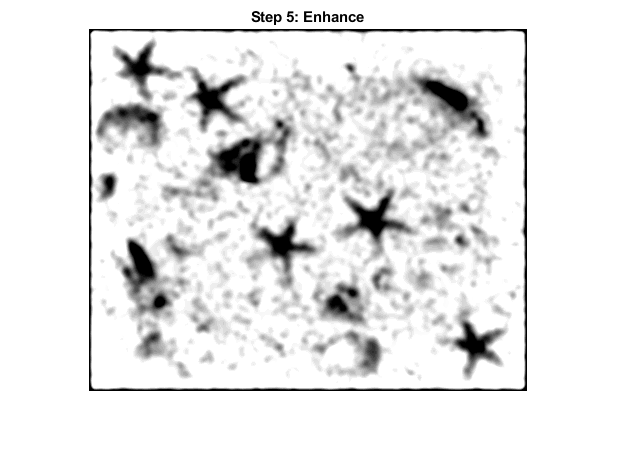

I4 = imgaussfilt(I4,2);
I4 = imadjust(I4);


I4 = imsharpen(I4,'Radius',40,'amount',0.8,'threshold',0);

imshow(I4), title('Step 5: Enhance');

T = graythresh(I4)

T = 0.6000

BW = imbinarize(I4,T);
binaryImage = imcomplement(BW)

binaryImage = 362×438 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

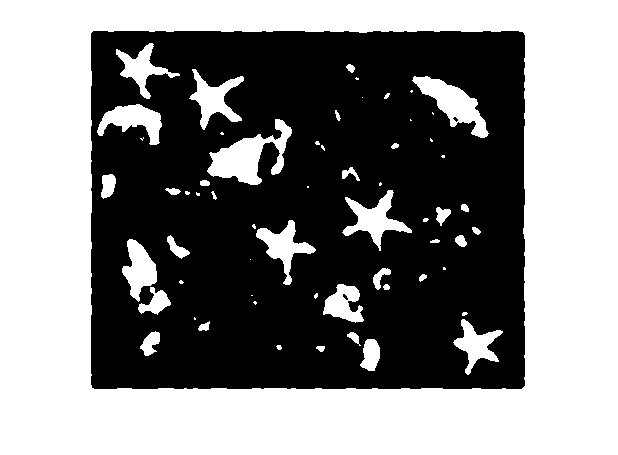

imshow(binaryImage)

%binaryImage = ~binaryImage;
%imshow(binaryImage)

% SE = strel( ...
%        [0  0  0  1  0  0  0 ; 
%         0  1  1  1  1  1  0 ; 
%         0  1  1  1  1  1  0 ; 
%         1  1  1  1  1  1  1 ; 
%         0  1  1  1  1  1  0 ; 
%         0  1  1  1  1  1  0 ; 
%         0  0  0  1  0  0  0 ])
SE=strel('disk',4)

SE = strel is a disk shaped structuring element with properties:

      Neighborhood: [7×7 logical]
    Dimensionality: 2


BW2 = bwareaopen(BW,200) 

BW2 = 362×438 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

J = imclose(BW2,SE)

J = 362×438 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1  

%SE = strel('rectangle',[2 5])
%J = imerode(binaryImage,SE)
FilteredImage=imcomplement(J)

FilteredImage = 362×438 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

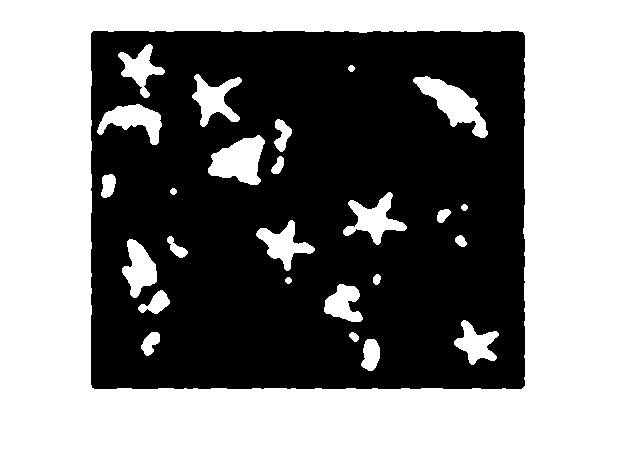

imshow(FilteredImage)

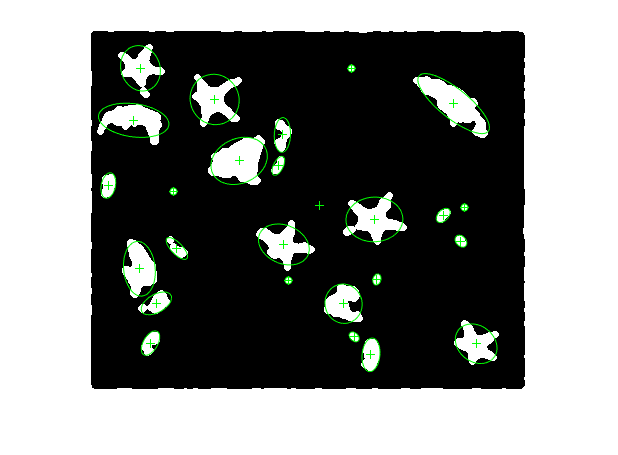

% Section 3: MSER Algorithm
% Built in function
% Detect and store regions.

% Which one should you use? Do we need ConnComp here?
[Regions, ConnComp] = detectMSERFeatures(FilteredImage);
Regions = detectMSERFeatures(FilteredImage);

% Display the centroids and axes of detected regions.
imshow(FilteredImage); hold on; plot(Regions); hold off;

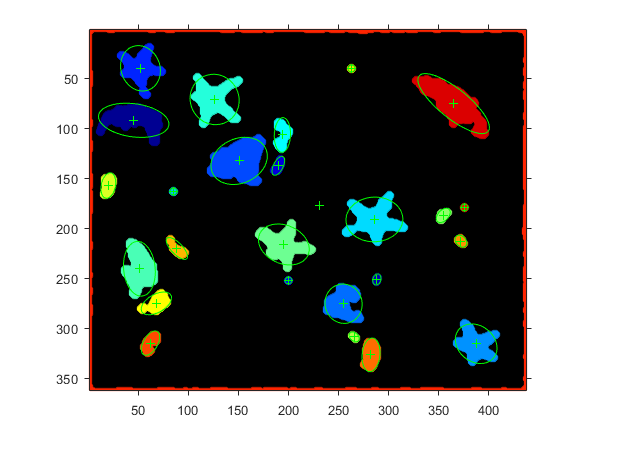

[Nregions, ~] = size( Regions );
if (Nregions > 100) 
    Nregions = 100;
end
imshow(FilteredImage); hold on;
plot(Regions(1:Nregions),'showPixelList', true),axis on;




% Using Results of MSER to find objects via regionprops etc.
% Use this section for five_objects.jpg or four_objects.jpg
% properties = regionprops(, 'all'); % uncomment if all metrics required
mserStats = regionprops(ConnComp, 'BoundingBox', 'Eccentricity', 'Solidity', 'Extent', 'Image','Extrema','Circularity','Area','Perimeter');
properties_table = regionprops('table',ConnComp, 'BoundingBox', 'Eccentricity', 'Solidity', 'Extent', 'Image','Extrema','Circularity','Area','Perimeter');
% show table
properties_table;

properties_table = sortrows(properties_table,'BoundingBox')

properties_table = 26×9 table
    Area              BoundingBox               Eccentricity    Circularity          Image            Extrema       Solidity    Extent     Perimeter
    ____    ________________________________    ____________    ___________    _________________    ____________    ________    _______    _________

    2243      1.5      1.5      436      360      0.50351        0.011644      {360×436 logical}    {8×2 double}    0.01429     0.01429     1555.9  
    1312      8.5     75.5       65       41      0.88433         0.42595      { 41×65  logical}    {8×2 double}     0.6583     0.49231     196.74  
     275     12.5    145.5       15       24      0.83693          

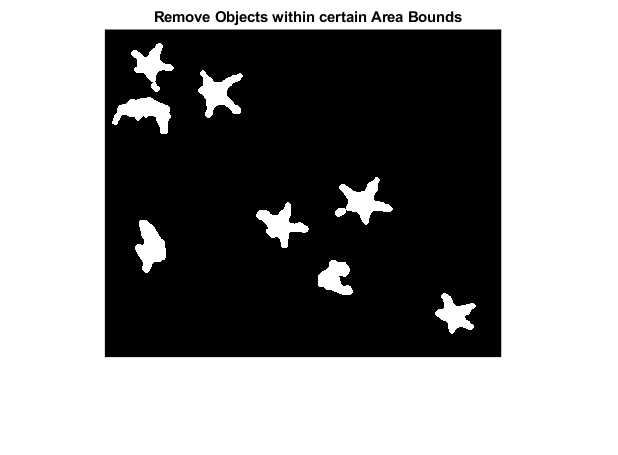

CC = bwconncomp(FilteredImage, 4);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);
BW5 = ismember(L, find([S.Area] >= 700 & [S.Area]<= 1550));
figure; hold on
imshow(BW5),title('Remove Objects within certain Area Bounds')

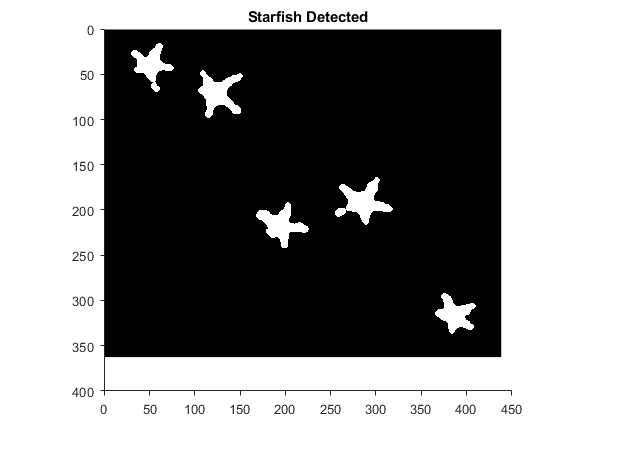

% selecting five point star
BW_out = BW5;
% Filter image based on image properties.

BW_out = bwpropfilt(BW_out, 'Eccentricity', [0.1, 0.75]);
BW_out = bwpropfilt(BW_out, 'Extent', [0.1, 0.58]);
BW_out = bwpropfilt(BW_out, 'Solidity', [0.1, 0.808]);
% Get rid of blobs with low circularity.

%0.87
%BW_out = bwpropfilt(BW_out, 'Circularity', [0, 0.7]);
figure; hold on
imshow(BW_out); title('Starfish Detected');axis on; hold off;

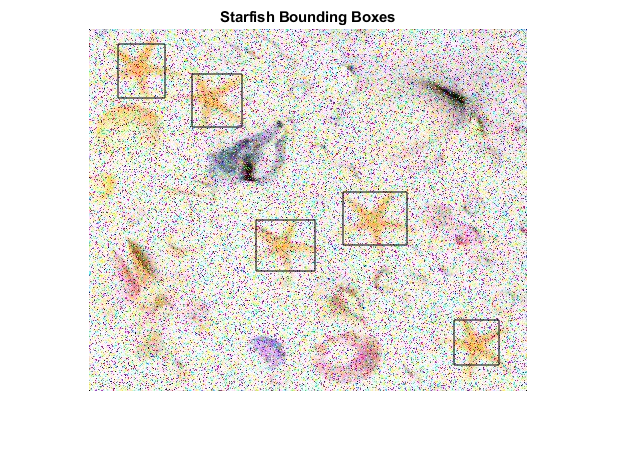



starfish = regionprops(BW_out, 'BoundingBox');
imshow(Img),title('Starfish Bounding Boxes'); hold on;
hold on
for k = 1 : length(starfish)
    thisBB = starfish(k).BoundingBox;
    hold on;
    rectangle('Position', thisBB);
end

fprintf("Starfish: " + length(starfish))

Starfish: 5